## **Detect the internal contours of the left ventricle (LV) on a Magnetic Resonance  Image (MRI) using the Snakes segmentation method**

#### **BOUGHEDADA  Aymen Lokmane**

**04/10/2022**

im=imread("irm_1.jpg");
im=im(:,:,1)

im = 121×165 uint8 matrix
    27    28    29    30    30    30    30    30    33    27    27    32    33    28    29    36    28    29    28    25    28    34    35    32    40    42    36    28    38    65    87    94   108   142   168   167   161   164   166   160   154   148   136   120   102    83    63    50    43    49
    31    30    29    28    29    30    32    34    36    30    29    33    33    28    29    34    41    29    25    31    30    24    28    41    37    48    45    31    41    81   114   125   134   162   181   175   163   160   157   150   154   142   127   112    92    70    54    49    55    61
    34    32    29    27    28    30    34    36    36    32    31    33    32    29    29    33    35    31    30    32    29    23    28    39    43    54    49    34    48    94   136   152   169   188   199   190   175   165   158   151   148   128   109    97    76    51    43    50    70    76
    31    30    29    28    28    30    32    34    32    31    30    3

imshow(im);
title('irm');

G=im2double(im);
figure(1)
imshow(G);
title('image en double');
hold on
alpha = 0.1; % élasticité : Specifies the elasticity of the snake. This controls the tension in the contour by combining with the first derivative term ?
beta = 0.5; % rigidité :Specifies the rigidity in the contour by combining with the second derivative term. ? 
gamma = 10; % viscosité : Specifies the step size 
kappa = 2; % pondération force externe pour… Acts as the scaling factor for the energy term?
kappap = 0.2; % pondération force du ballon pour….limits the elongation and deformation of the curve ?
Niter = 20; % fréquence de rééchantillonnage : number for sample to define the new pixel position
ITER = 30; % nombre d'itérations total (à optimiser) : specifies the number of iterations for which contour’s position is to be computed
dmax = 2; % paramètres de rééchantillonnage du contour :clamp contour to boundary ?
dmin = 0.5; 
delta = 0.3; % pas d'échantillonnage initial

H = fspecial('gaussian',[3 3],0.3);
out = imfilter(G,H,'replicate');    
figure(2)
subplot(2,2,1)
imshow(im)
title('original')
subplot(2,2,2)
imshow(G)
title('double')
subplot(2,2,3)
imshow(out)
title('after applying gaussian filter')
hold on

%%applying 
[px, py] = gradient(out);

normegrad = (sqrt(px.^2+py.^2));
figure(3);

quiver(px(1:3:end,1:3:end), py(1:3:end,1:3:end));

quiver(px, py);
hold on

deformation du snake

figure(5)
subplot(2,2,1),imshow(im);title('original image');
subplot(2,2,2),imshow(gradient(out));title('gradient image');
hold on 

you asked us to show the original image and the gradient 

but for applying snake algorithme i did use the filtred image 

figure (6)
imshow(out)
delta=1;
[x,y] = snakeinit(delta);

Bouton de gauche pour selectionner un point
Bouton de droite pour terminer la selection


for i=1:ITER
    [x,y] = snakedeform(x,y,alpha,beta,gamma,kappa, kappap,px,py,Niter);
    hold on; plot(x,y,'yellow'); hold off;
    pause(0.5)
    [x,y] = snakeinterp(x,y,dmax,dmin);
    %compteur = compteur + 1;
    
end

hold on

7) Show the final result on the original image (hold on, plot)

figure(7)
imshow(im)
hold on
x=[x;x(1)];
y=[y;y(1)];
hold on, plot(x,y,'x-g');title('image segmente');
hold on

8) Parameters study : we'll show the effect of the parameter alpha and beta on the final result

For beta=0

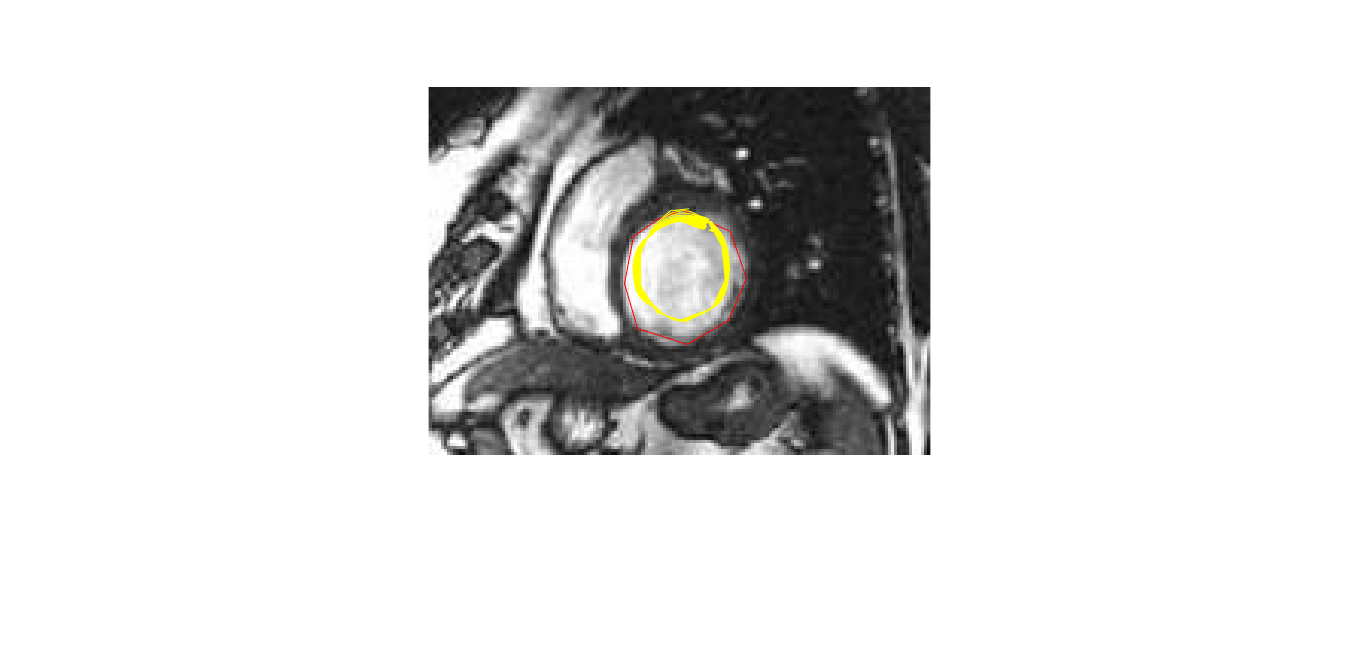

Bouton de gauche pour selectionner un point
Bouton de droite pour terminer la selection


alpha = 0.1; 
beta = 0; 
gamma = 10; 
kappa = 2; 
kappap = 0.2; 
Niter = 20; 
ITER = 30; 
dmax = 2; 
dmin = 0.5; 
delta = 0.3;

figure (8)
imshow(out)
delta=1;
[x,y] = snakeinit(delta);

for i=1:ITER
    [x,y] = snakedeform(x,y,alpha,beta,gamma,kappa, kappap,px,py,Niter);
    hold on; plot(x,y,'yellow'); hold off;
    pause(0.5)
    [x,y] = snakeinterp(x,y,dmax,dmin);
    %compteur = compteur + 1;
    
end
hold on
figure(9)
imshow(im)
hold on
x=[x;x(1)];
y=[y;y(1)];
hold on, plot(x,y,'x-g');title('image segmente');
hold on

now for beta=5

alpha = 0.1; 
beta = 5; 
gamma = 10; 
kappa = 2; 
kappap = 0.2; 
Niter = 20; 
ITER = 30; 
dmax = 2; 
dmin = 0.5; 
delta = 0.3;

figure (10)
imshow(out)
delta=1;
[x,y] = snakeinit(delta);

Bouton de gauche pour selectionner un point
Bouton de droite pour terminer la selection


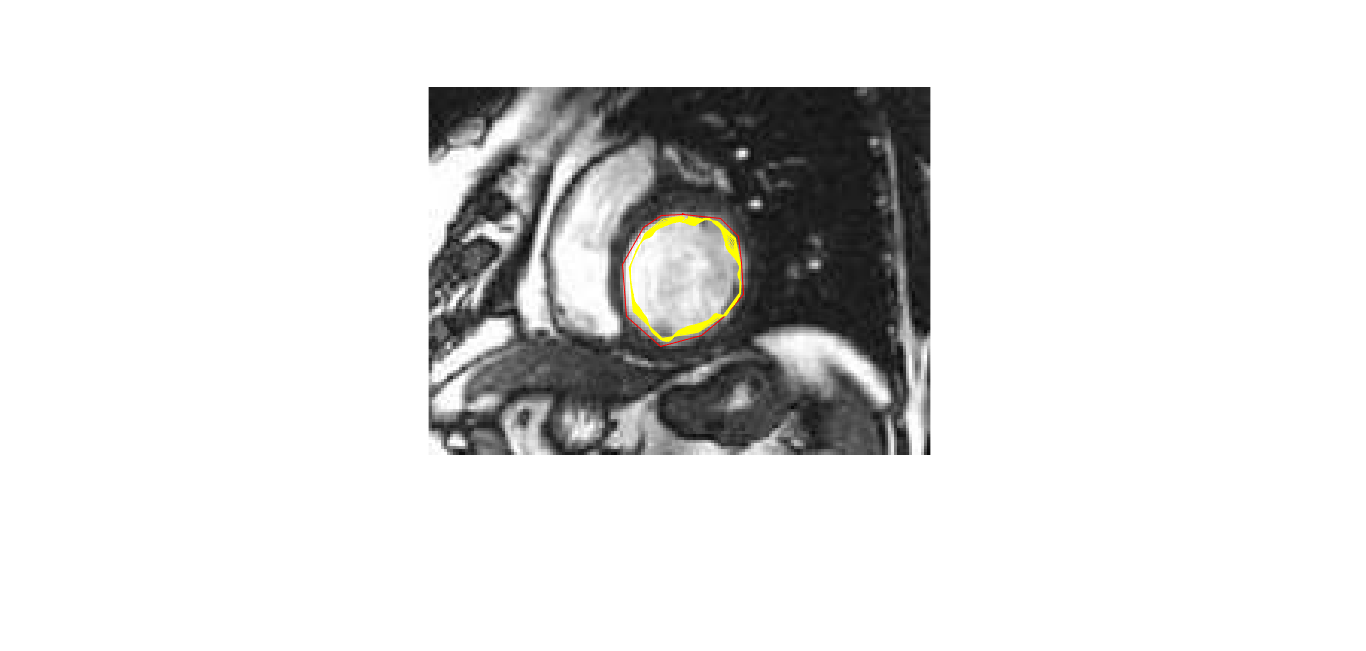

for i=1:ITER
    [x,y] = snakedeform(x,y,alpha,beta,gamma,kappa, kappap,px,py,Niter);
    hold on; plot(x,y,'yellow'); hold off;
    pause(0.5)
    [x,y] = snakeinterp(x,y,dmax,dmin);
    %compteur = compteur + 1;
    
end

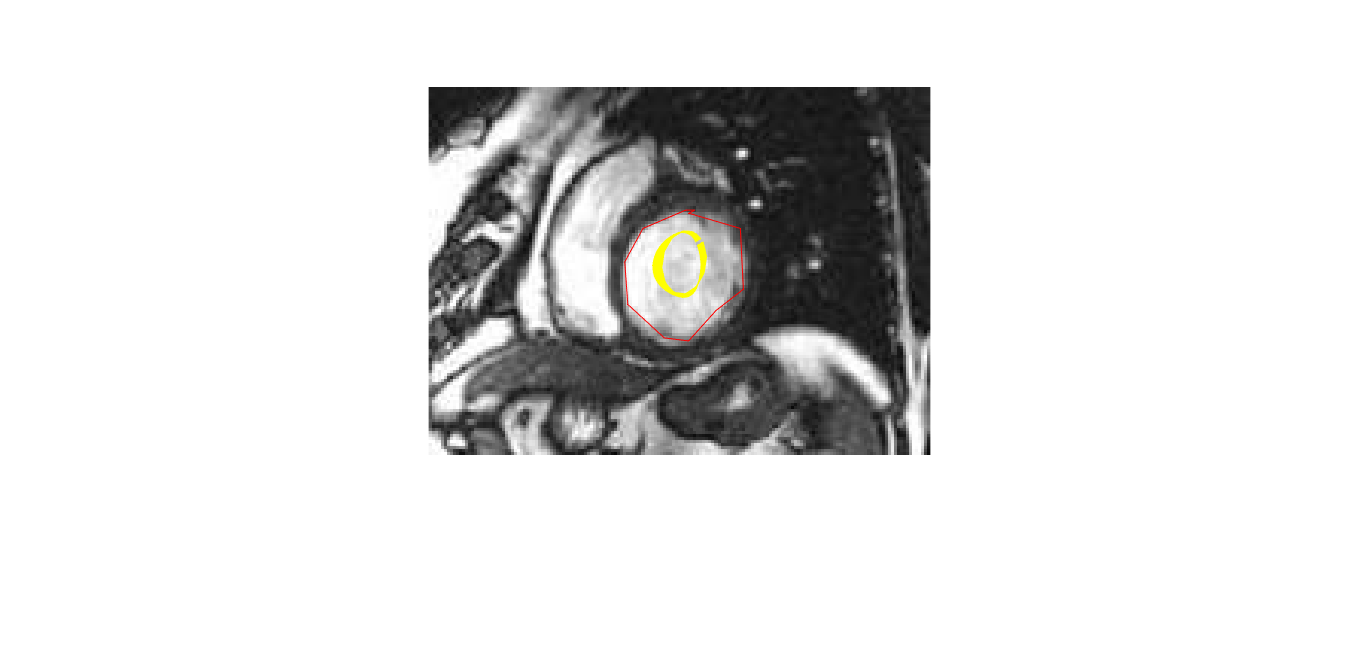

hold on

figure(11)
imshow(im)
hold on
x=[x;x(1)];
y=[y;y(1)];
hold on, plot(x,y,'x-g');title('image segmente');
hold on

Observation : by modifiying beta wich is related to the rigidity we can observe : when beta is close to zero we notice that the snake contour stay close to the region selected if we increase the beta the snake contour goes away from the region selected beta control the rigidity of our snake

Test the program for the values alpha=0 then for alpha=5

for alpha =00

alpha = 0; % élasticité : Specifies the elasticity of the snake. This controls the tension in the contour by combining with the first derivative term ?
beta = 0.5; % rigidité :Specifies the rigidity in the contour by combining with the second derivative term. ? 
gamma = 10; % viscosité : Specifies the step size 
kappa = 2; % pondération force externe pour… Acts as the scaling factor for the energy term?
kappap = 0.2; % pondération force du ballon pour….limits the elongation and deformation of the curve ?
Niter = 20; % fréquence de rééchantillonnage : ?
ITER = 30; % nombre d'itérations total (à optimiser) : specifies the number of iterations for which contour’s position is to be computed
dmax = 2; % paramètres de rééchantillonnage du contour :clamp contour to boundary ?
dmin = 0.5; 
delta = 0.3; % pas d'échantillonnage initial
figure (12)
imshow(out)
delta=1;
[x,y] = snakeinit(delta);

Bouton de gauche pour selectionner un point
Bouton de droite pour terminer la selection


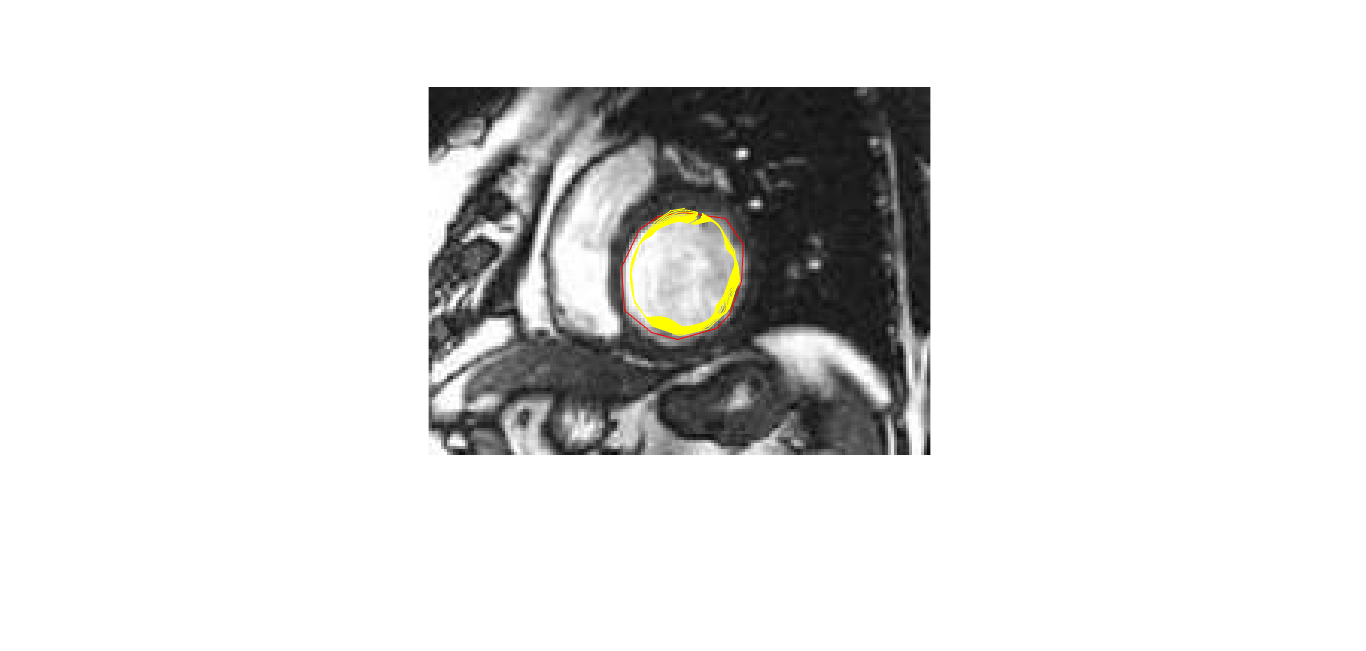

for i=1:ITER
    [x,y] = snakedeform(x,y,alpha,beta,gamma,kappa, kappap,px,py,Niter);
    hold on; plot(x,y,'yellow'); hold off;
    pause(0.5)
    [x,y] = snakeinterp(x,y,dmax,dmin);
    %compteur = compteur + 1;
    
end
hold on

figure(13)
imshow(im)
hold on
x=[x;x(1)];
y=[y;y(1)];
hold on, plot(x,y,'x-g');title('image segmente');
hold on

for alpha = 05

alpha = 05; % élasticité : Specifies the elasticity of the snake. This controls the tension in the contour by combining with the first derivative term ?
beta = 0.5; % rigidité :Specifies the rigidity in the contour by combining with the second derivative term. ? 
gamma = 10; % viscosité : Specifies the step size 
kappa = 2; % pondération force externe pour… Acts as the scaling factor for the energy term?
kappap = 0.2; % pondération force du ballon pour….limits the elongation and deformation of the curve ?
Niter = 20; % fréquence de rééchantillonnage : ?
ITER = 30; % nombre d'itérations total (à optimiser) : specifies the number of iterations for which contour’s position is to be computed
dmax = 2; % paramètres de rééchantillonnage du contour :clamp contour to boundary ?
dmin = 0.5; 
delta = 0.3; % pas d'échantillonnage initial
figure (14)
imshow(out)
delta=1;
[x,y] = snakeinit(delta);

Bouton de gauche pour selectionner un point
Bouton de droite pour terminer la selection


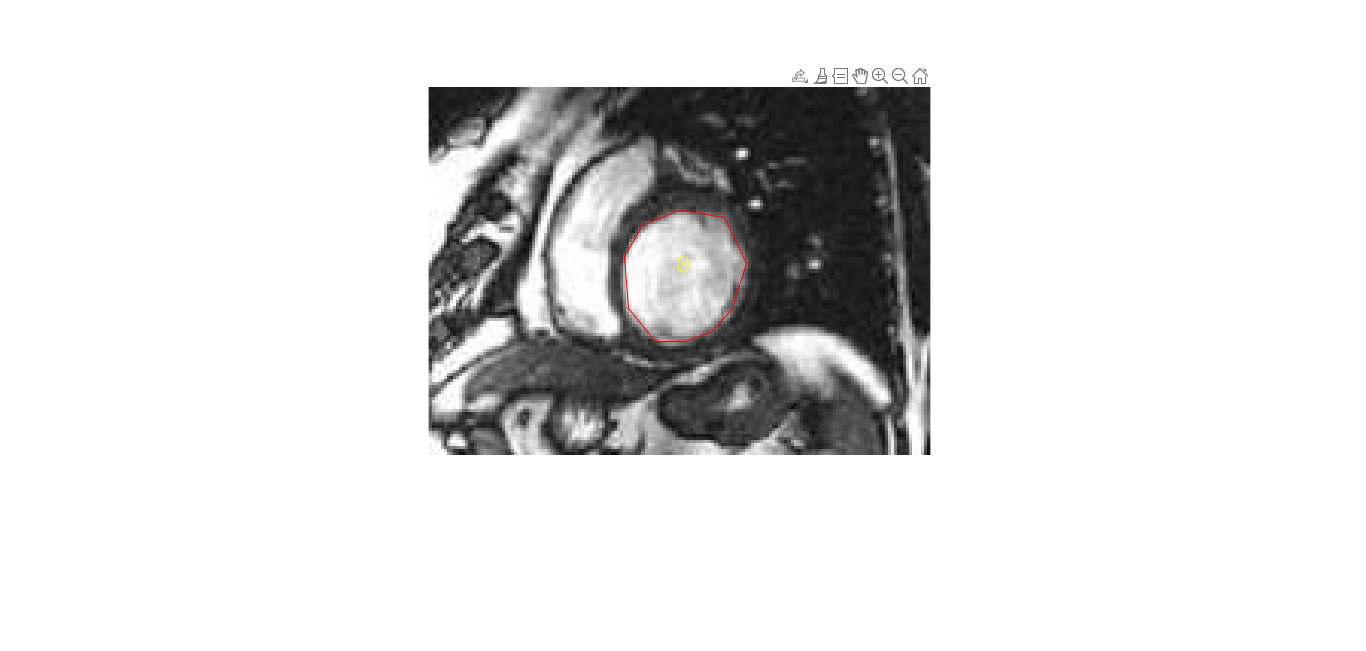

Index exceeds the number of array elements. Index must not exceed 0.

Error in snakeinterp (line 18)
d = abs(x([2:N 1])- x(:)) + abs(y([2:N 1])- y(:));

for i=1:ITER
    [x,y] = snakedeform(x,y,alpha,beta,gamma,kappa, kappap,px,py,Niter);
    hold on; plot(x,y,'yellow'); hold off;
    pause(0.5)
    [x,y] = snakeinterp(x,y,dmax,dmin);
    %compteur = compteur + 1;
    
end

hold on
figure(15)
imshow(im)
hold on
x=[x;x(1)];
y=[y;y(1)];
hold on, plot(x,y,'x-g');title('image segmente');
hold on

we can notice that the alpha parameter act like beta but on the elasticity of the snake

since high values of this differential imply a high rate of change in that region of the contour(big value of alpha imply low region of snake)

## Conclusion

An image segmentation system using active contour have been designed and implemented.

Different values of alpha, beta have been observed as well, for our case best result are obtained when both of alpha and beta are in range of 0 and 1.

as conclusion fine tunning of all the parameters may improve the internal contour of the left ventricle